# Improve an Engine Cooling Fan: Design for Six Sigma

This example shows how to improve the performance of an engine cooling fan through a **Design for Six Sigma approach using Define, Measure, Analyze, Improve, and Control (DMAIC).** The initial fan does not circulate enough air through the radiator to keep the engine cool during difficult conditions. First, the example shows how to design an experiment to investigate the effect of three performance factors: *fan distance from the radiator*, *blade-tip clearance*, and *blade pitch angle*. It then shows how to estimate optimum values for each factor, resulting in a design that produces airflows beyond the goal of 875 $\text{ft}^3/\text{min} $ using test data. Finally, it shows how to use simulations to verify that the new design produces airflow according to the specifications in more than 99.999% of the fans manufactured. This example uses MATLAB®, Statistics and Machine Learning Toolbox™, and Optimization Toolbox™.

## **1. Define the Problem**

This example addresses an engine cooling fan design that is unable to pull enough air through the radiator to keep the engine cool during difficult conditions, such as stop-and-go traffic or hot weather). Suppose you estimate that you need airflow of at least 875 $\text{ft}^3/\text{min} $ to keep the engine cool during difficult conditions. You need to evaluate the current design and develop an alternative design that can achieve the target airflow.

## **2. Assess, Analyse Cooling Fan Performance: No/Low-Code Approaches**

#### Import `originalfan.xlsx` as numeric data using importData APP on the HOME tab ribbon or:

uiimport % can also "drag 'n drop" input data file into the workspace

The data consists of 10,000 measurements (historical production data) of the existing cooling fan performance.

Plot the data to analyze the current fan's performance.

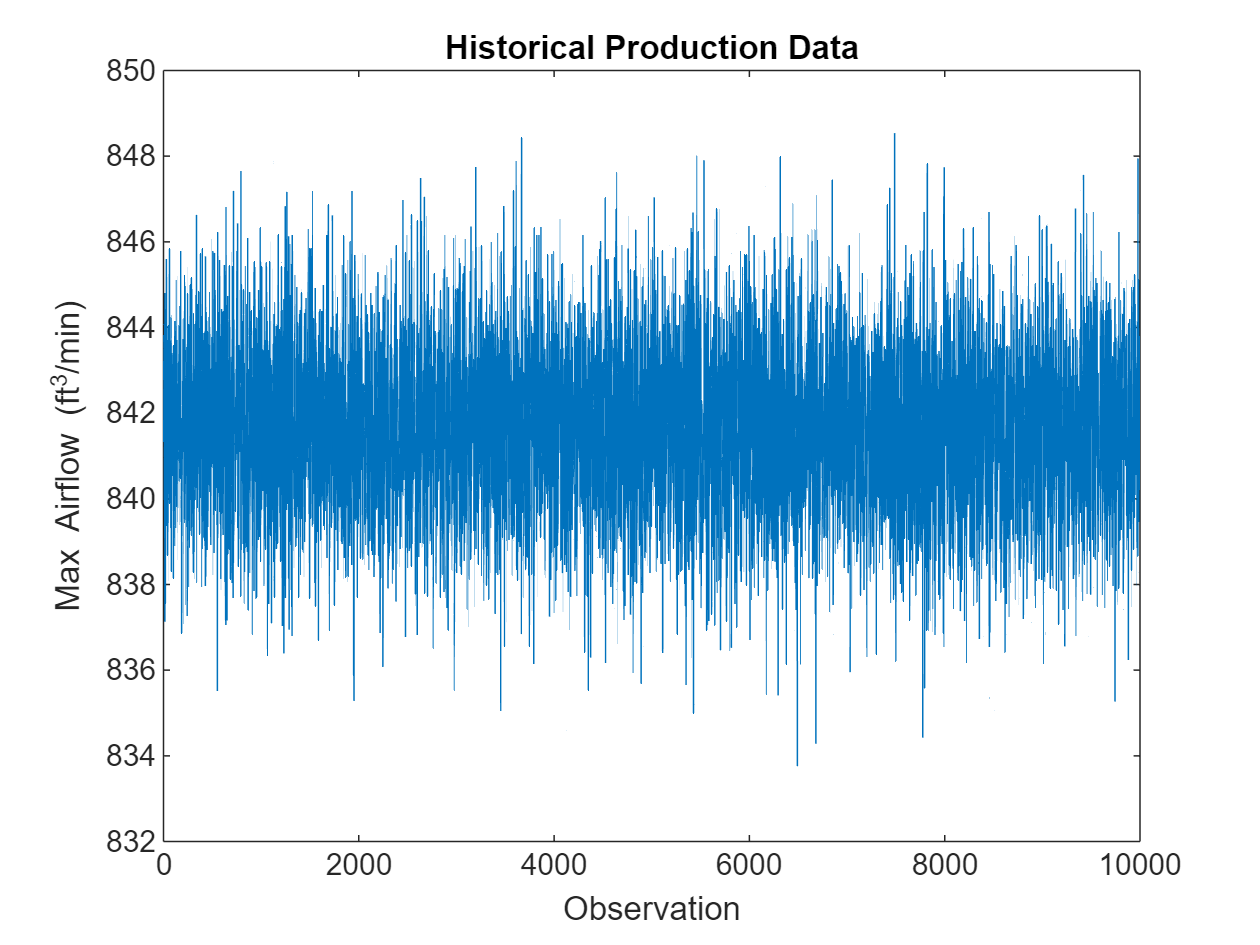

% Create plot of originalfan
h2 = plot(originalfan,"DisplayName","originalfan");

% Add ylabel, title, and legend
ylabel("originalfan")

title("originalfan")
legend

plot(originalfan)

T = 10000×1 table
    originalfan
    ___________

      844.07   
      842.14   
      841.35   
       841.7   
      843.49   
      839.09   
      843.47   
      839.98   
      840.97   
      841.37   
      839.18   
       840.5   
      842.48   
      837.13   
       844.8   
      839.83   


xlabel('Observation')
ylabel('Max Airflow (ft^3/min)')
title('Historical Production Data')

The data is centered around 842 $\text{ft}^3/\text{min} $ and most values fall within the range of about 8 $\text{ft}^3/\text{min} $. The plot does not tell much about the underlying distribution of data, however. 

#### NOTE: If data needs to be conditioned, then map the data to a table and use the dataCleaner APP.

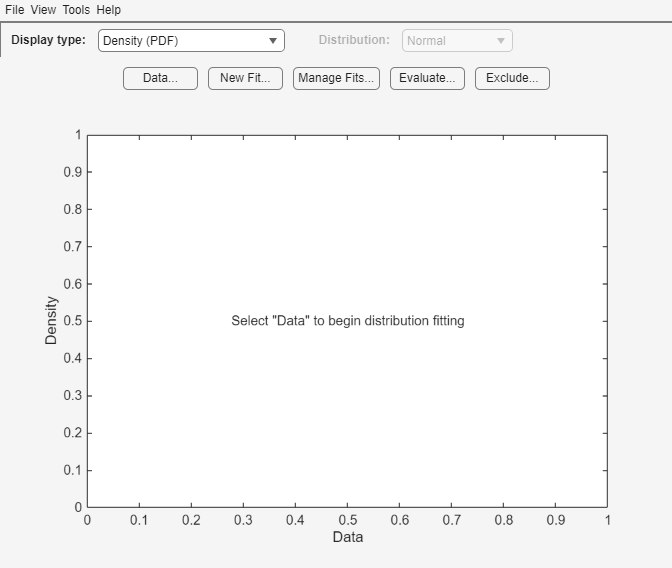

T = array2table(originalfan)

dataCleaner % can also open app directly from the 'Home' tab ribbon                  

#### Use the distributionFitter APP to assess the data distribution.  

distributionFitter

#### Alternatively:

Plot the histogram and fit a normal distribution to the data.

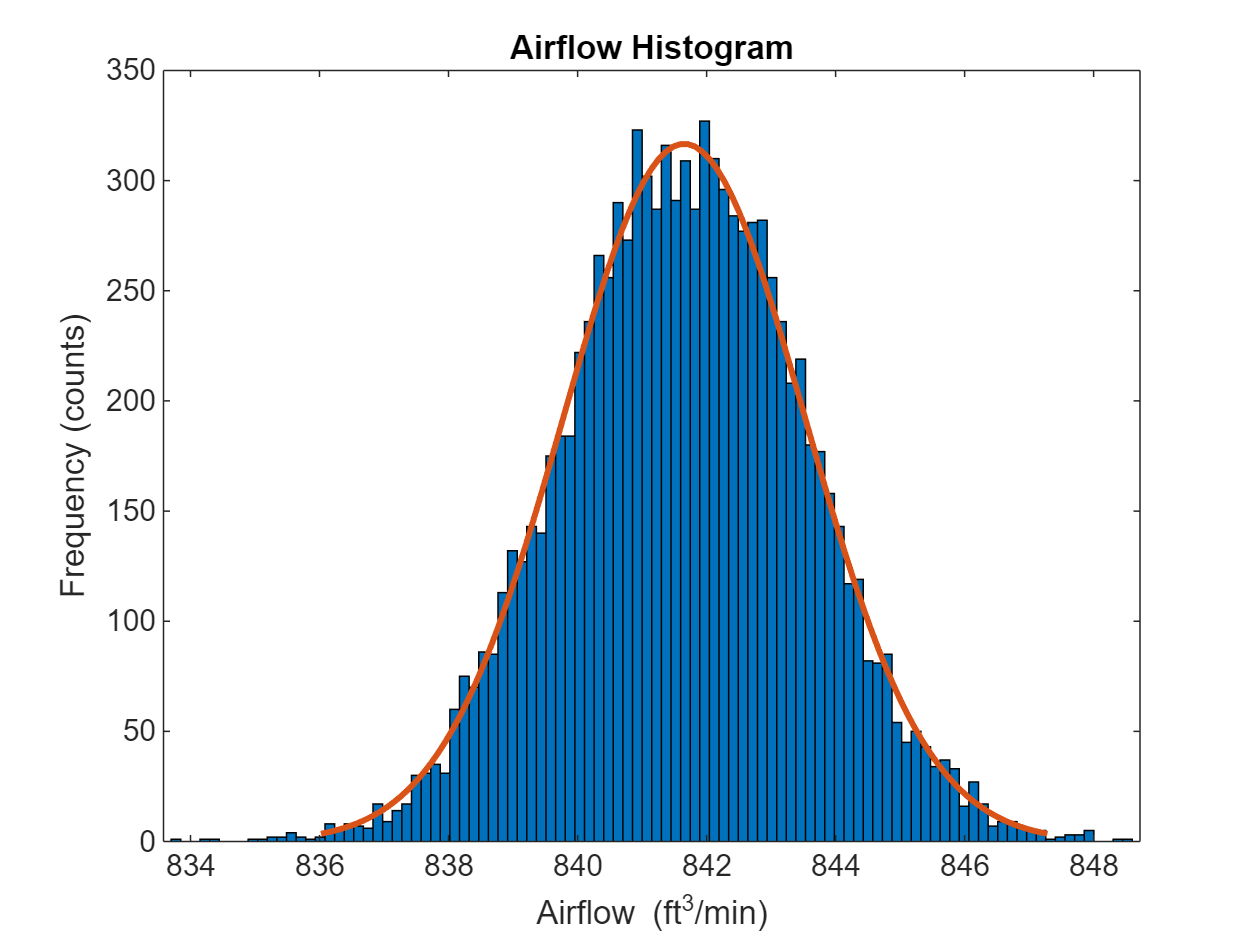

histfit(originalfan) % Plot histogram with normal distribution fit
xlabel('Airflow (ft^3/min)')

ylabel('Frequency (counts)')

pd =   NormalDistribution

  Normal distribution
       mu = 841.652   [841.616, 841.689]
    sigma =  1.8768   [1.85114, 1.90318]


title('Airflow Histogram')
pd = fitdist(originalfan,'normal') % Fit normal distribution to data

[`fitdist`](http://www.mathworks.com/help/stats/fitdist.html) fits a normal distribution to data and estimates the parameters from data. The estimate for the mean airflow speed is 841.652 $\text{ft}^3/\text{min} $, and the 95% confidence interval for the mean airflow speed is (841.616, 841.689). This estimate makes it clear that the current fan is not close to the required 875 $\text{ft}^3/\text{min} $. There is need to improve the fan design to achieve the target airflow.

## **3. Design-Of-Experiments: Determine Factors That Affect Performance**

Evaluate the factors that affect cooling fan performance using **design of experiments (DOE)**. The response is the cooling fan airflow rate ($\text{ft}^3/\text{min} $). Suppose that the factors that you can modify and control are:

- **Distance from radiator**

- **Pitch angle**

- **Blade tip clearance**

In general, fluid systems have nonlinear behavior. Therefore, use a response surface design to estimate any nonlinear interactions among the factors. Generate the experimental runs for a [Box-Behnken design](http://www.mathworks.com/help/stats/bbdesign.html) in coded (normalized) variables [-1, 0, +1].

CodedValue = bbdesign(3)

CodedValue =     -1    -1     0
    -1     1     0
     1    -1     0
     1     1     0
    -1     0    -1
    -1     0     1
     1     0    -1
     1     0     1
     0    -1    -1
     0    -1     1


The first column is for the distance from radiator, the second column is for the pitch angle, and the third column is for the blade tip clearance. Suppose you want to test the effects of the variables at the following minimum and maximum values.

- **Distance from radiator: 1 to 1.5 inches**

- **Pitch angle: 15 to 35 degrees **

- **Blade tip clearance: 1 to 2 inches**

Randomize the order of the runs, convert the coded design values to real-world units, and perform the experiment in the order specified.

runorder = randperm(15);     % Random permutation of the runs
bounds = [1 1.5;15 35;1 2];  % Min and max values for each factor
format shortg

RealValue = zeros(size(CodedValue));
for i = 1:size(CodedValue,2) % Convert coded values to real-world units
    zmax = max(CodedValue(:,i));
    zmin = min(CodedValue(:,i));
    RealValue(:,i) = interp1([zmin zmax],bounds(i,:),CodedValue(:,i));
end
disp(RealValue)

            1           15          1.5
            1           35          1.5
          1.5           15          1.5
          1.5           35          1.5
            1           25            1
            1           25            2
          1.5           25            1
          1.5           25            2
         1.25           15            1
         1.25           15            2
         1.25           35            1
         1.25           35            2
         1.25           25          1.5
         1.25           25          1.5
         1.25           25          1.5



Suppose the at the end of the experiments, you collect the following response values in the variable `TestResult`.

TestResult = [837 864 829 856 880 879 872 874 834 833 860 859 874 876 875]';

Display the design values and the response.

disp(array2table(sortrows([runorder' RealValue TestResult]),...
    'VariableNames',{'RunNumber','Distance','Pitch','Clearance','Airflow'}))

    RunNumber    Distance    Pitch    Clearance    Airflow
    _________    ________    _____    _________    _______

        1          1.25       15           1         834  
        2          1.25       15           2         833  
        3             1       35         1.5         864  
        4          1.25       35           1         860  
        5           1.5       25           1         872  
        6             1       15         1.5         837  
        7           1.5       35         1.5         856  
        8             1       25           2         879  
        9          1.25       25         1.5         874  
       10          1.25       25         1.5         876  
       11           1.5       15         1.5         829  
       12          1.25       25         1.5         875  
   

Save the design values and the response in a `table`.

Expmt = table(runorder', CodedValue(:,1), CodedValue(:,2), CodedValue(:,3), ...
    TestResult,'VariableNames',{'RunNumber','D','P','C','Airflow'})

Expmt = 15×5 table
    RunNumber    D     P     C     Airflow
    _________    __    __    __    _______

        6        -1    -1     0      837  
        3        -1     1     0      864  
       11         1    -1     0      829  
        7         1     1     0      856  
       14        -1     0    -1      880  
        8        -1     0     1      879  
        5         1     0    -1      872  
       15         1     0     1      874  
        1         0    -1    -1      834  
        2         0    -1     1      833  
        4         0     1    -1      860  
       13         0     1     1      859  
        9         0     0     0      874  
       10         0     0     0      876  
       12         0     0     0      875  


`D` stands for `Distance`, `P` stands for `Pitch`, and C stands for `Clearance`. Based on the experimental test results, the airflow rate is sensitive to the changing factors values. Also, four experimental runs meet or exceed the target airflow rate of 875 $\text{ft}^3/\text{min} $ (runs 2, 4,12, and 14). However, it is not clear which, if any, of these runs is the optimal one. In addition, it is not obvious how robust the design is to variation in the factors. Create a model based on the current experimental data and use the model to estimate the optimal factor settings.

## **4. Optimised Modelling: Improve the Cooling Fan Performance**

#### Fit Model

The Box-Behnken design enables you to test for nonlinear (quadratic) effects. The form of the quadratic model is:


$$AF = \beta 0+\beta 1*Distance+\beta 2*Pitch+\beta 3*Clearance+\beta 4*Distance*Pitch+\beta 5\ast Distance\ast Clearance \\ \qquad+ \beta 6\ast Pitch\ast Clearance+\beta 7\ast Distance^2+\beta 8\ast Pitch^2+\beta 9\ast Clearance^2
\end{multline*}$$


where *AF* is the airflow rate and $\text{B}_i$ is the coefficient for the term *i*. Estimate the coefficients of this model using the [`fitlm`](http://www.mathworks.com/help/stats/fitlm.html) function from Statistics and Machine Learning Toolbox.

mdl = fitlm(Expmt(:,2:5),'Airflow~D*P*C-D:P:C+D^2+P^2+C^2')

mdl = Linear regression model:
    Airflow ~ 1 + D*P + D*C + P*C + D^2 + P^2 + C^2

Estimated Coefficients:
                    Estimate       SE         tStat         pValue  
                   __________    _______    __________    __________

    (Intercept)           875    0.56273        1554.9    2.0882e-15
    D                  -3.625     0.3446       -10.519    0.00013403
    P                   13.25     0.3446         38.45    2.2422e-07
    C                  -0.125     0.3446      -0.36274       0.73163
    D:P            2.2723e-13    0.48734    4.6628e-13             1
    D:C                  0.75    0.48734         1.539       0.18443
    P:C            1.6168e-15    0.48734    3.3175e-15             1
    D^2

Display the magnitudes of the coefficients (for normalized values) in a bar chart.

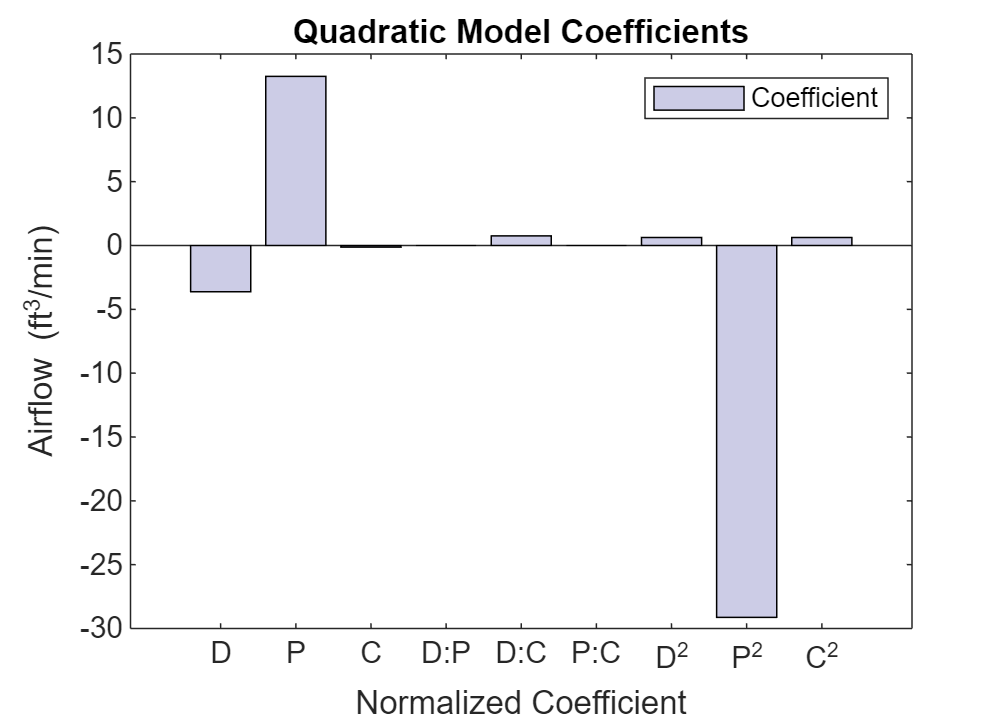

figure('Units','normalized','Position',[0.05 0.4 0.35 0.4])
h = bar(mdl.Coefficients.Estimate(2:10));
set(h,'FaceColor',[0.8 0.8 0.9]);
legend('Coefficient')
set(gca,'XTickLabel',mdl.CoefficientNames(2:10));
ylabel('Airflow (ft^3/min)')
xlabel('Normalized Coefficient')
title('Quadratic Model Coefficients')

The bar chart shows that *Pitch* and $\textit{Pitch}^2$ are dominant factors. You can look at the relationship between multiple input variables and one output variable by generating a response surface plot. Use [`plotSlice`](http://www.mathworks.com/help/stats/compactlinearmodel.plotslice.html) to generate response surface plots for the model `mdl` interactively.

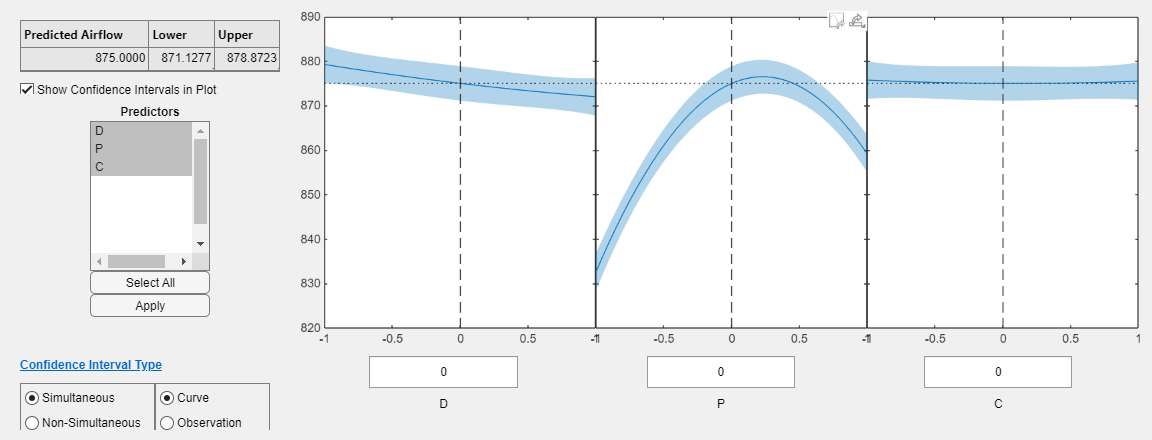

plotSlice(mdl)

The plot shows the nonlinear relationship of airflow with pitch. Move the blue dashed lines around and see the effect the different factors have on airflow. 

#### Optimise Model

Although you can use `plotSlice` to determine the optimum factor settings, you can also use Optimization Toolbox to automate the task.

Find the optimal factor settings using the constrained optimization function `fmincon`.

Write the objective function using `predict(mdl,x);`

The objective function is a quadratic response surface fit to the data. We are looking to maximize the objective function. The constraints are the upper and lower limits tested (in coded values) [-1, 1]. Set the initial starting point to be the center of the design of the experimental test matrix.

prob = optimproblem("ObjectiveSense","maximize");
x = optimvar('optimFactors',1,3,'LowerBound',-1,'UpperBound',1);
x0.optimFactors = zeros(1,3); % Starting point
prob.Objective = fcn2optimexpr(@predict,mdl,x); % Converts function to optimization expression
options = optimoptions('fmincon','display','iter');
[sol, fval] = solve(prob,x0,'Options',options); % Invoke the solver


Solving problem using fmincon.
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       4    8.750000e+02    0.000e+00    8.833e+00
    1       9    8.756049e+02    0.000e+00    2.015e+01    5.905e-01
    2      13    8.801030e+02    0.000e+00    9.478e+00    6.986e-01
    3      17    8.819543e+02    0.000e+00    4.347e+00    8.551e-01
    4      22    8.816620e+02    0.000e+00    4.628e+00    1.438e-01
    5      27    8.818495e+02    0.000e+00    4.162e+00    7.405e-02
    6      31    8.819863e+02    0.000e+00    3.613e+00    4.544e-02
    7      35    8.820231e+02    0.000e+00    2.580e+00    2.208e-02
    8      39    8.820596e+02    0.000e+00    9.964e-02    4.436e-02
    9      43    8.822544e+02    0.000e+00    7.096e-02    4.930e-02
   10      47    8.822566e+02    0.000e+00    6.718e-03    7.182e-04
   11      51    8.822566e+02    0.000e+00    5.367e-03    3.279e-05
   12      55  

Convert the results to a maximization problem and real-world units.

maxval = fval;
optfactors = sol.optimFactors;
maxloc = (optfactors + 1)';
bounds = [1 1.5;15 35;1 2];
maxloc=bounds(:,1)+maxloc .* ((bounds(:,2) - bounds(:,1))/2);
disp(array2table([maxloc' maxval],'VariableNames',...
    {'Distance','Pitch','Clearance','Airflow'}))

    Distance    Pitch     Clearance    Airflow
    ________    ______    _________    _______

       1        27.275        1        882.26 



The optimization result suggests placing the new fan one inch from the radiator, with a one-inch clearance between the tips of the fan blades and the shroud.

Because pitch angle has such a significant effect on airflow, perform additional analysis to verify that a 27.3 degree pitch angle is optimal.

load 'Data/AirflowData.mat'
tbl = table(pitch,airflow);
mdl2 = fitlm(tbl,'airflow~pitch^2')

mdl2 = Linear regression model:
    airflow ~ 1 + pitch + pitch^2

Estimated Coefficients:
                   Estimate       SE         tStat       pValue  
                   ________    _________    _______    __________

    (Intercept)      676.23       2.1727     311.24    2.4225e-66
    pitch            15.135      0.18043     83.882    9.6031e-45
    pitch^2        -0.27788    0.0035887    -77.433    1.9732e-43


Number of observations: 41, Error degrees of freedom: 38
Root Mean Squared Error: 0.719
R-squared: 0.996,  Adjusted R-Squared: 0.996
F-statistic vs. constant model: 5.14e+03, p-value = 5.78e-47

The results show that a quadratic model explains the effect of pitch on the airflow well.

Plot the pitch angle against airflow and impose the fitted model.

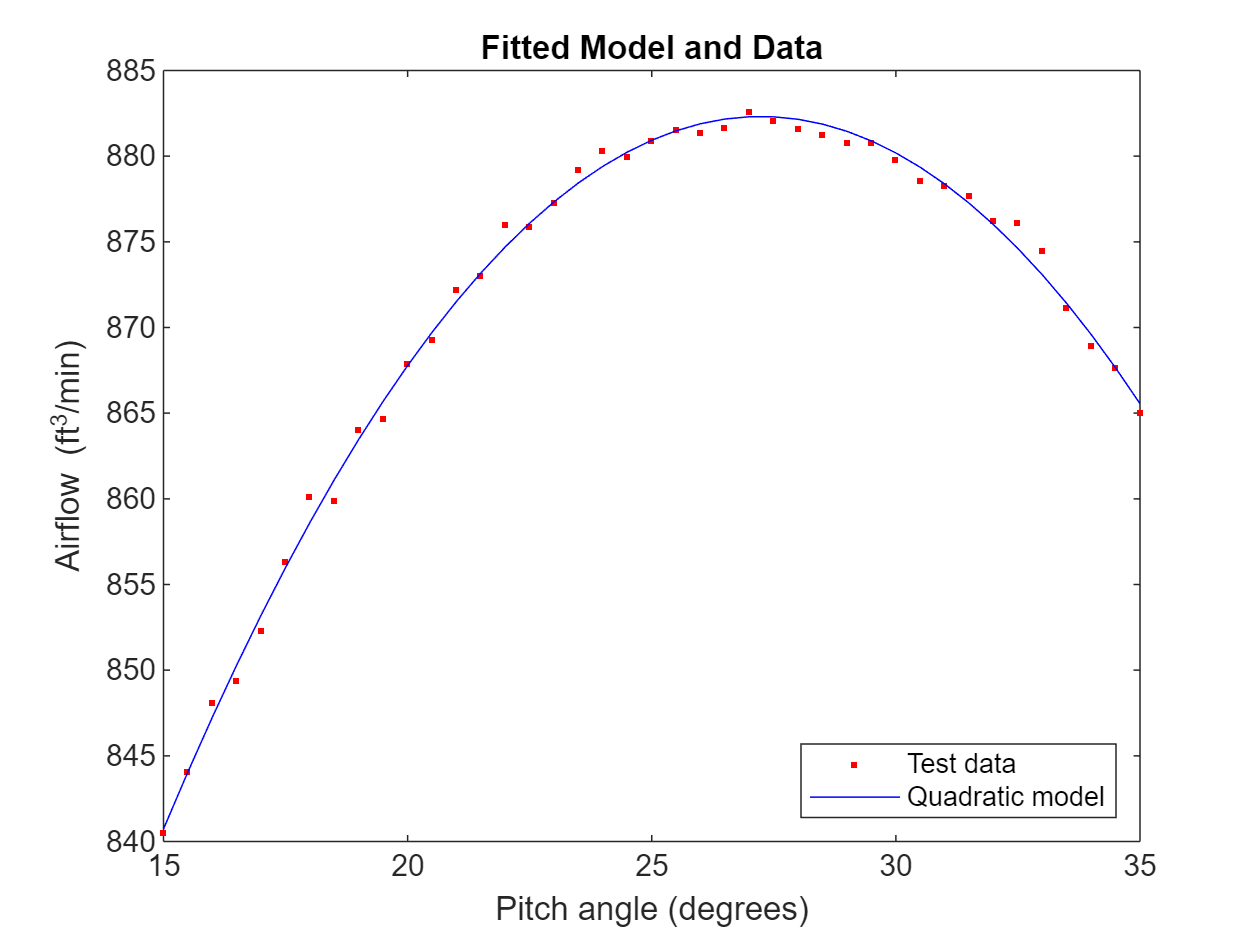

figure
plot(pitch,airflow,'.r')
hold on
ylim([840 885])
line(pitch,mdl2.Fitted,'color','b')
title('Fitted Model and Data')
xlabel('Pitch angle (degrees)')
ylabel('Airflow (ft^3/min)')
legend('Test data','Quadratic model','Location','se')
hold off

Find the pitch value that corresponds to the maximum airflow.

[~, idx] = max(airflow);
disp(pitch(idx))

    27



The additional analysis confirms that a 27.3 degree pitch angle is optimal.

The improved cooling fan design meets the airflow requirements. You also have a model that approximates the fan performance well based on the factors you can modify in the design. Ensure that the fan performance is robust to variability in manufacturing and installation by performing a sensitivity analysis.

## **5. Assess Model: Sensitivity Analysis**

Suppose that, based on historical experience, the manufacturing uncertainty is as follows.

`      Factor: Real Values, Coded Values`

- Distance from radiator: 1.00 +/- 0.05 inch, 1.00 +/- 0.20 inch

- Blade pitch angle: 27.3 +/- 0.25 degrees, 0.227 +/- 0.028 degrees

- Blade tip clearance: 1.00 +/- 0.125 inch, -1.00 +/- 0.25 inch

Verify that these variations in factors will enable to maintain a robust design around the target airflow. The philosophy of Six Sigma targets a defect rate of no more than 3.4 per 1,000,000 fans. That is, the fans must hit the 875 $\text{ft}^3/\text{min} $ target 99.999% of the time.

You can verify the design using Monte Carlo simulation. Generate 10,000 random numbers for three factors with the specified tolerance. First, set the state of the random number generators so results are consistent across different runs.

rng('default')

Perform the Monte Carlo simulation. Include a noise variable that is proportional to the noise in the fitted model, `mdl` (that is, the RMS error of the model). Because the model coefficients are in coded variables, you must generate `dist`, `pitch`, and `clearance` using the coded definition.

dist = random('normal',optfactors(1),0.20,[10000 1]);
pitch = random('normal',optfactors(2),0.028,[10000 1]);
clearance = random('normal',optfactors(3),0.25,[10000 1]);
noise = random('normal',0,mdl2.RMSE,[10000 1]);

Calculate airflow for 10,000 random factor combinations using the model.

simfactor = [dist pitch clearance];
X = predict(mdl,simfactor);

Add noise to the model (the variation in the data that the model did not account for).

simflow = X + noise;

Evaluate the variation in the model's predicted airflow using a histogram. To estimate the mean and standard deviation, fit a normal distribution to data.

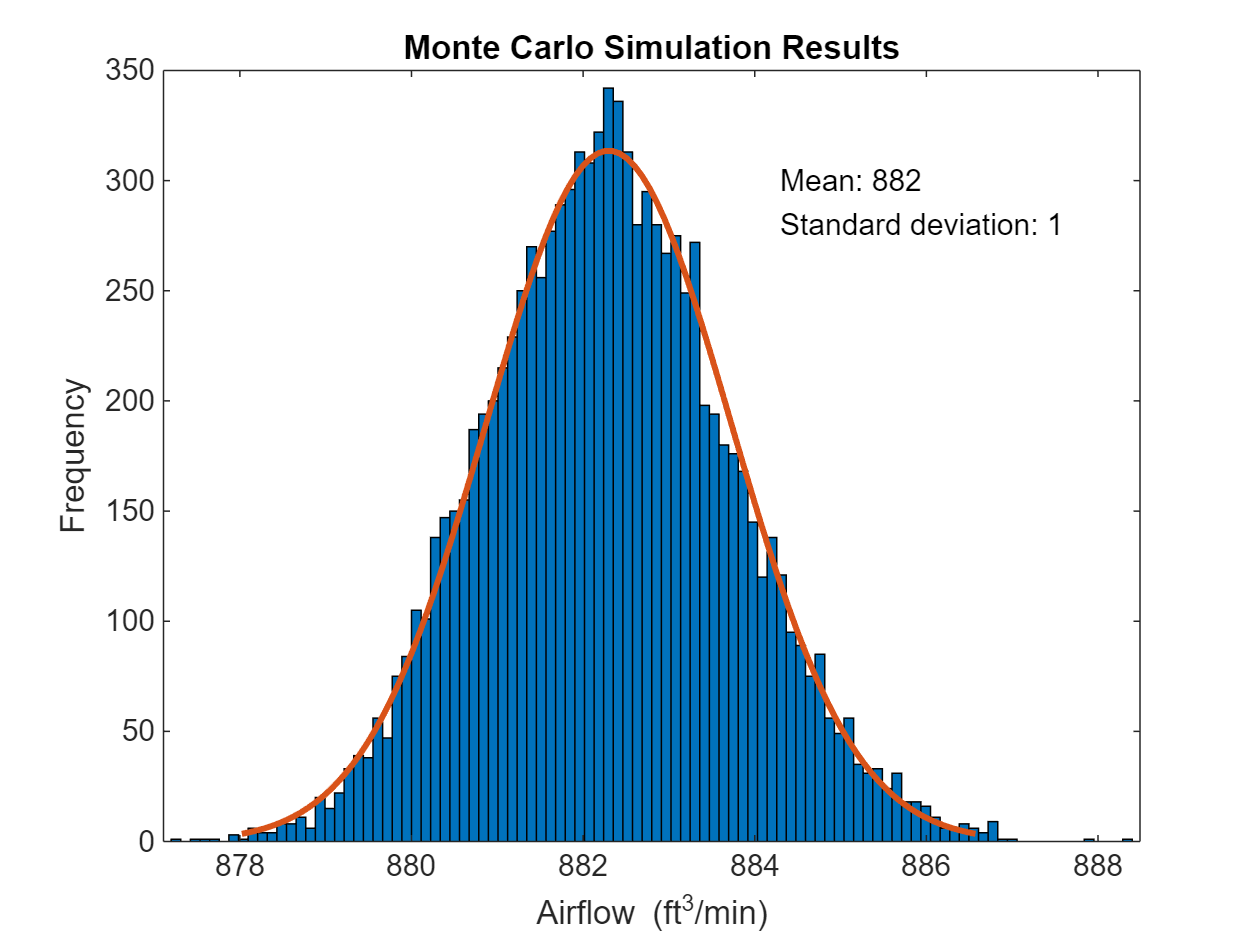

pd = fitdist(simflow,'normal');
histfit(simflow)
hold on
text(pd.mu+2,300,['Mean: ' num2str(round(pd.mu))])
text(pd.mu+2,280,['Standard deviation: ' num2str(round(pd.sigma))])
hold off
xlabel('Airflow (ft^3/min)')
ylabel('Frequency')
title('Monte Carlo Simulation Results')

The results look promising. The average airflow is 882 $\text{ft}^3/\text{min} $ and appears to be better than 875 $\text{ft}^3/\text{min} $ for most of the data.

Determine the probability that the airflow is at 875 $\text{ft}^3/\text{min} $ or below.

format long
pfail = cdf(pd,875)

pfail =      1.509288967210659e-07


pass = (1-pfail)*100

pass =   99.999984907110331


The design appears to achieve at least 875 $\text{ft}^3/\text{min} $ of airflow 99.999% of the time.

Use the simulation results to estimate the process capability.

S = capability(simflow,[875.0 890])

S = struct with fields:
       mu: 8.822982645663780e+02
    sigma: 1.424806875428719
        P: 0.999999816749821
       Pl: 1.509288967210659e-07
       Pu: 3.232128233668679e-08
       Cp: 1.754623762078464
      Cpl: 1.707427790680271
      Cpu: 1.801819733476657
      Cpk: 1.707427790680271


pass = (1-S.Pl)*100

pass =   99.999984907110331


The `Cp` value is 1.75. A process is considered high quality when `Cp` is greater than or equal to 1.6. The `Cpk` is similar to the `Cp` value, which indicates that the process is centered. Now implement this design. Monitor it to verify the design process and to ensure that the cooling fan delivers high-quality performance.

## **6. Evaluate Model: Control Manufacturing of the Improved Cooling Fan**

You can monitor and evaluate the manufacturing and installation process of the new fan using control charts. Evaluate the first 30 days of production of the new cooling fan. Initially, five cooling fans per day were produced. First, load the sample data from the new process.

load 'Data/spcdata.mat'

Plot the *X*-bar and *S* charts.

figure
controlchart(spcflow,'chart',{'xbar','s'}) % Reshape the data into daily sets
xlabel('Day')

According to the results, the manufacturing process is in statistical control, as indicated by the absence of violations of control limits or nonrandom patterns in the data over time. 

You can also run a capability analysis on the data to evaluate the process.

S2 = capability(spcflow(:),[875.0 890])
pass = (1-S.Pl)*100

The `Cp` value of 1.755 is very similar to the estimated value of 1.73. The `Cpk` value of 1.66 is smaller than the `Cp` value. However, only a `Cpk` value less than 1.33, which indicates that the process shifted significantly toward one of the process limits, is a concern. The process is well within the limits and it achieves the target airflow (875 $\text{ft}^3/\text{min} $) more than 99.999% of the time.

# Multi-Criteria Decision Making

## 7. **Technique for Order Preference by Similarity to Ideal Solution (**TOPSIS**)**

The TOPSIS (Technique for Order of Preference by Similarity to Ideal Solution) method is a multi-criteria decision-making technique used to evaluate and rank alternatives based on their similarity to ideal solutions. It works by normalizing scores for each criterion and calculating the geometric distance between each alternative and the ideal solution, with the goal of minimizing distance to the ideal and maximizing distance from the negative ideal.  TOPSIS is particularly useful in scenarios where the decision-maker needs to balance multiple criteria and where the data is not fully defined or precise.  The technique provides a structured approach to decision-making, allowing for the selection of the most suitable alternative based on the criteria set.  As such, it is widely applied in various fields, including business, engineering, and healthcare, to handle complex decision-making problems by allowing trade-offs between conflicting objectives. In particular, this method is applied in ranking machine learning models on basis of various factors like correlation, R^2, RMS-error, accuracy, precision, F-score, etc. 

#### Algorithm

- **Define the Problem:** Identify problem and determine the evaluation criteria for decision alternatives.

- **Construct a Decision Matrix:** Create a matrix with alternatives as rows and criteria as columns.

- **Normalize the Decision Matrix:** Ensure each criterion receives equal weight by normalizing the values.

- **Determine the Weighted Normalized Decision Matrix:** Assign weights to each criterion based on their importance.

- **Determine the Positive and Negative Ideal Solutions:** Identify the best and worst possible values for each criterion.

- **Calculate the Separation Measures:** Compute the Euclidean distance of each alternative from the positive and negative ideal solutions.

- **Calculate the Relative Closeness to the Ideal Solution:** Determine the closeness of each alternative to the ideal solution and rank the alternatives based on these values.

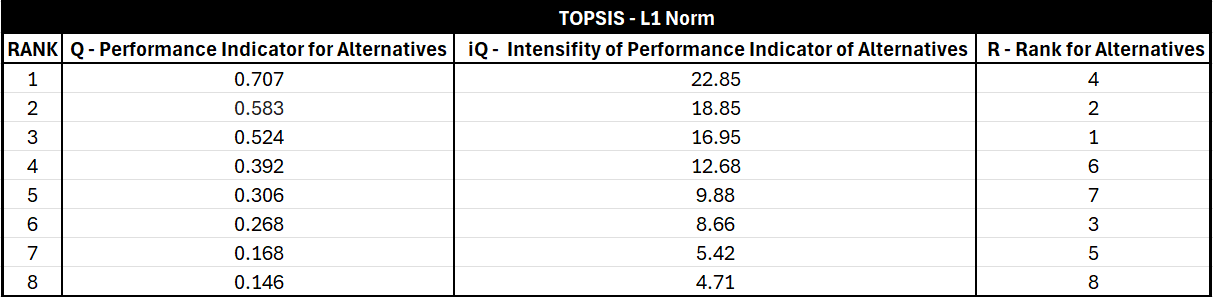

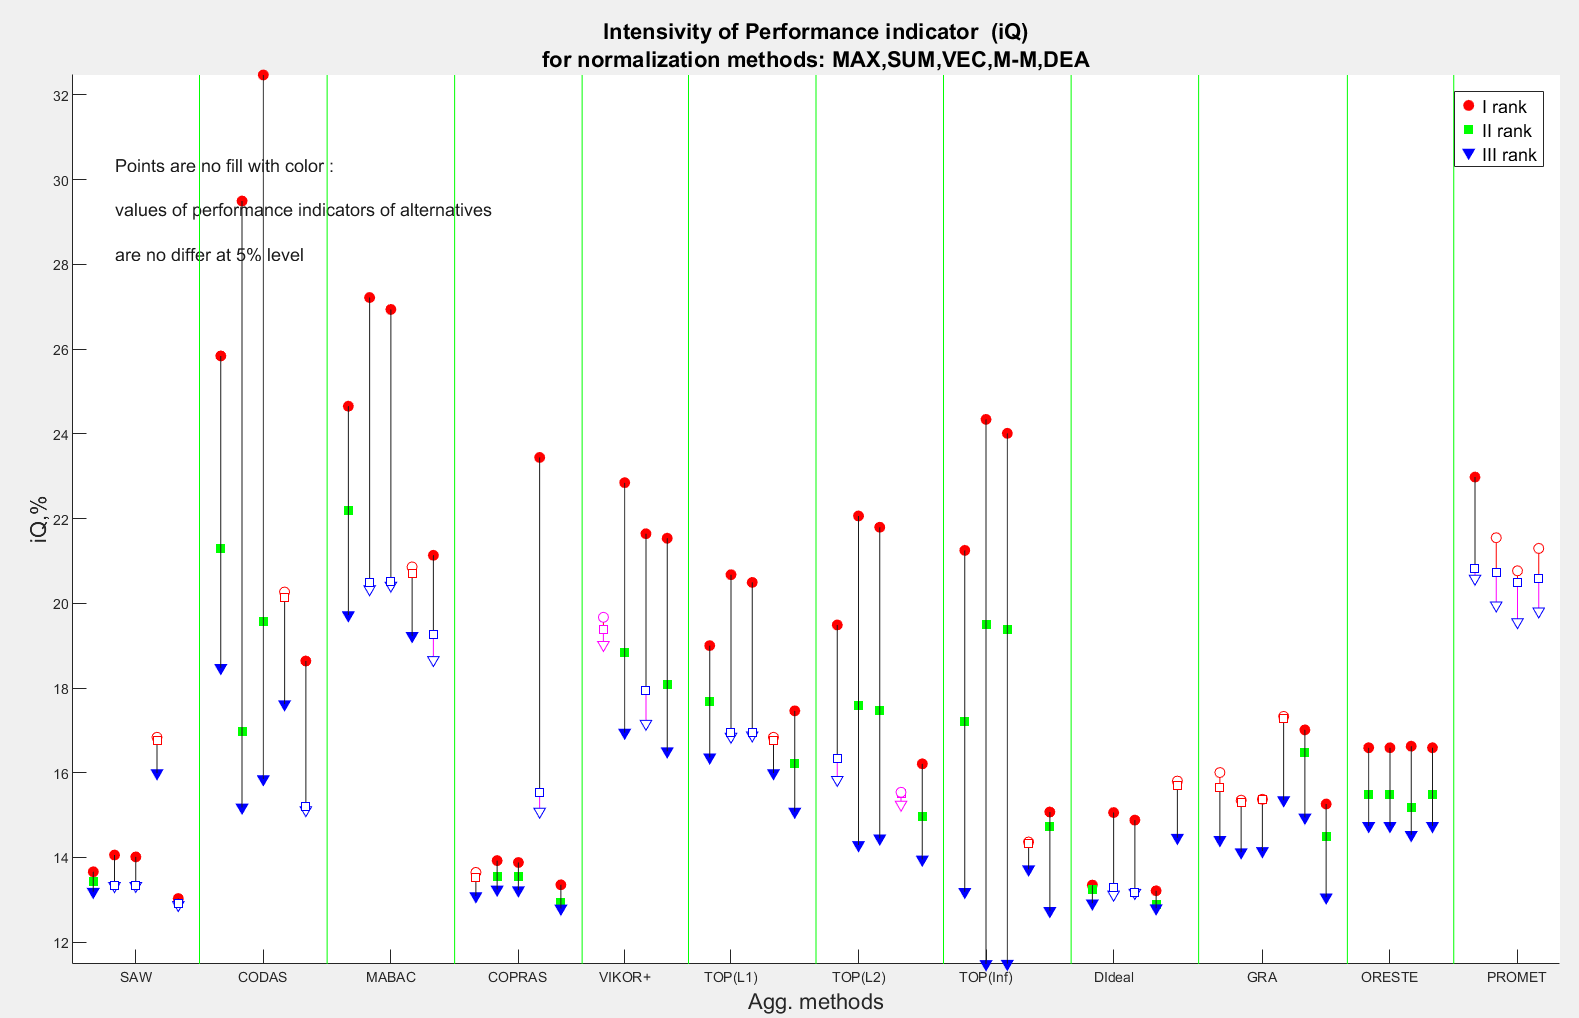

### **FOR FULL DETAILS: download** [`MCDM_tools`](https://www.mathworks.com/matlabcentral/fileexchange/65742-mcdm-tools) **from the File Exchange on MATLAB Central and explore (to generate MCDM examples, run MCDM_tools.m).**